% --- CONFIG ---
port = "COM10";      
baud = 115200;
outfile = "samples.csv";

% --- OPEN SERIAL ---
s = serialport(port, baud);
configureTerminator(s, "LF");

disp("Waiting for START...");

Waiting for START...



data = [];
recording = false;

while true
    line = readline(s);
    line = strtrim(line);

    if line == "START"
        disp("Recording started");
        recording = true;
        continue
    end

    if line == "END"
        disp("Recording ended");
        break
    end

    if recording
        val = str2double(line);
        if ~isnan(val)
            data(end+1) = val; %#ok<AGROW>
        end
    end
end

Recording started


Recording ended



% --- SAVE TO CSV ---
writematrix(data', outfile);
disp("Saved to samples.csv");

Saved to samples.csv


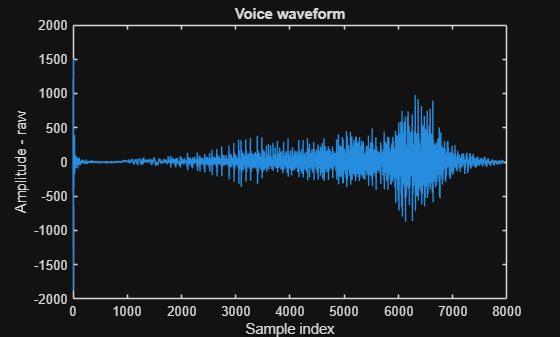


%% Read Audio Signal
signal = readmatrix("samples.csv");
fs = 8000;       % Sampling frequency
audio = signal;

%% Time Axis
t = (0:length(audio)-1) / fs;

%% FFT Parameters
Nfft = 4096;
window = hann(Nfft);

%% Select Short Frame (quasi-stationary)
frame = audio(1:Nfft) .* window;

%% FFT
X = fft(frame, Nfft);
X = abs(X(1:Nfft/2+1));              % One-sided magnitude
f = (0:Nfft/2) * fs / Nfft;

%% Normalize Spectrum
X = X / max(X);
X_db = 20*log10(X + eps);

%% ---- Band-pass for 300-3400 Hz ----
f_low = 300;
f_high = 3400;

% Indices within desired frequency band
band_idx = (f >= f_low) & (f <= f_high);

% Filter frequency and spectrum
f_band = f(band_idx);
X_db_band = X_db(band_idx);

%% Peak Detection within band
[pks, locs_idx] = findpeaks(X_db_band, f_band, ...
    "MinPeakHeight", -40, ...
    "MinPeakDistance", 40);

%% ---- Plot ----
figure

% Raw data
plot(data);
xlabel("Sample index");
ylabel("Amplitude - raw");
title("Voice waveform");

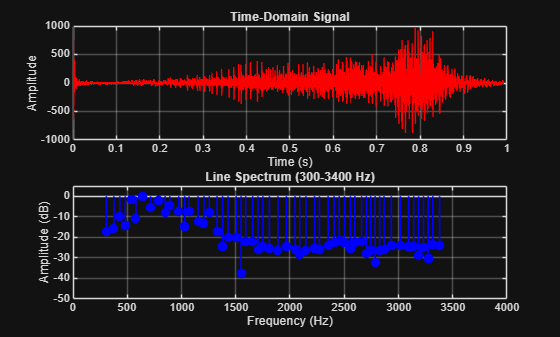


% Time-domain signal
subplot(2,1,1)
plot(t, audio, 'r', 'LineWidth', 1)
grid on
xlabel("Time (s)")
ylabel("Amplitude")
title("Time-Domain Signal")
xlim([0 1])
ylim([-1000 1000])

% Line spectrum (300-3400 Hz)
subplot(2,1,2)
stem(locs_idx, pks, 'b', 'filled', 'LineWidth', 1.2)
grid on
xlabel("Frequency (Hz)")
ylabel("Amplitude (dB)")
title("Line Spectrum (300-3400 Hz)")
ylim([-50 5])
xlim([0 4000])


% 1. Fundamental frequency (F0) - Autocorrelation
frame = audio(1:2048);
frame = frame - mean(frame);

r = xcorr(frame);
r = r(length(frame):end);   % keep positive lags only

% Search for peaks in 50–400 Hz range
minLag = floor(fs/400);
maxLag = floor(fs/50);

[~, lag] = max(r(minLag:maxLag));
lag = lag + minLag - 1;

f0 = fs / lag;


% 2. Top 3 spectral peaks 
[topVals, topIdx] = maxk(mag, 3); 
topFreqs = f(topIdx); 

% 3. RMS energy 
rmsVal = sqrt(mean(audio.^2)); 

% 4. Spectral centroid 
centroid = sum(f(:) .* mag(:)) / sum(mag); 

% 5. Zero-crossing rate 
zcr = sum(abs(diff(audio > 0))) / length(audio);

% Calculate and display results
disp("Fundamental Frequency (F0): " + f0);

Fundamental Frequency (F0): 400


disp("Top 3 Spectral Peaks: " + join(string(topFreqs), ", "));

Top 3 Spectral Peaks: 115.2344, 117.1875, 103.5156


disp("RMS Energy: " + rmsVal);

RMS Energy: 132.1861


disp("Spectral Centroid: " + centroid);

Spectral Centroid: 1017.165


disp("Zero-Crossing Rate: " + zcr);

Zero-Crossing Rate: 0.19758
